clear all
data = load('text-mining-medline_stemmed.mat');

dict = data.dict;
A = data.A;
k = 100;
c = 50;

query_index = 1

% Import testing data
relevantDocs = importdata('text-mining-medline/text-mining-medline/MED.REL');
relevantDocs = relevantDocs(relevantDocs(:,1)==query_index,3)

%Choose query


query_index = 1

query = data.q(:,query_index);
getQueryWords(query, dict)

ans = 5×21 char array
    'crystallin           '
    'human                '
    'includ               '
    'len                  '
    'vertebr              '



% Compute matrixes and query vector
[Hk, lsi_qk] = LSI(A, query, k);
[Gk, c_qk] = Clustering(A, query, c);


relevantDocs =     13
    14
    15
    72
    79
   138
   142
   164
   165
   166


tol = 0.2:0.05:0.85;
% Calculate precision and recall
[lsi_precision,lsi_recall,c_precision,c_recall] = getPrecAndRec(Hk, lsi_qk, Gk, c_qk, relevantDocs, tol);



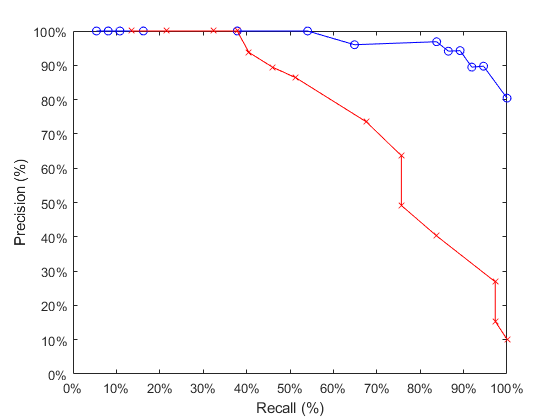

clf
plotPrecAndRec(lsi_precision,lsi_recall,c_precision,c_recall);